## Part 2 : Processing Sleep Patterns of New Babies

New born baby sleep cycle :

load Data/EEG/data.mat

### Assigning index to each sleep stage

-  qt - Quiet sleep, trace alternant 

- qh - Quiet sleep, high voltage

- tr - Transitional sleep

- al - Active sleep, low voltag

- ah - Active sleep, high voltage

- aw - Awake

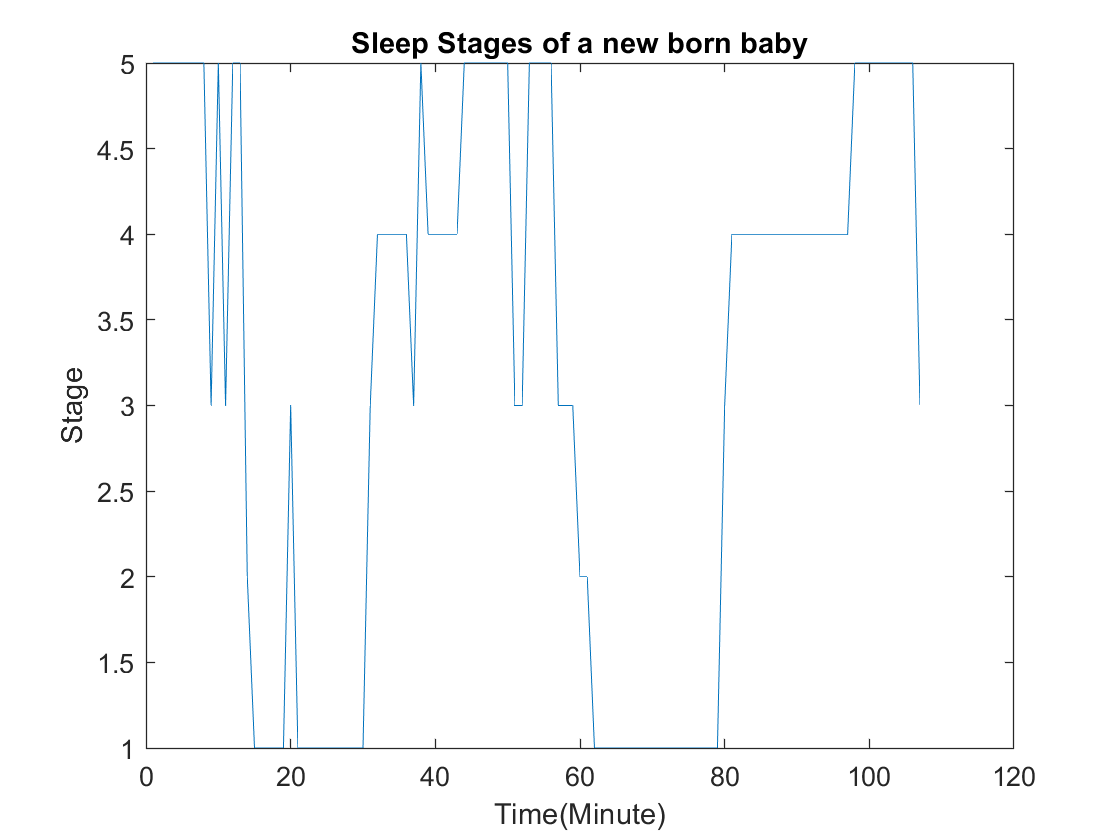

len = length(data);
data2 = zeros(1,len);
for i = 1:len
    if data(i) == "qt"
        data2(i) = 1;
    elseif data(i) == "qh"
        data2(i) = 2;
    elseif data(i) == "tr"
        data2(i) = 3;
    elseif data(i) == "al"
        data2(i) = 4;
    elseif data(i) == "ah"
        data2(i) = 5;
    elseif data(i) == "aw"
        data2(i) = 6;
    end
end

plot(data2);
title("Sleep Stages of a new born baby");
ylabel("Stage");
xlabel("Time(Minute)");

## Fourier Transform of Sleep Stages

fft_sleep_stages = fft(data2);

## Graph of Fourier Transform

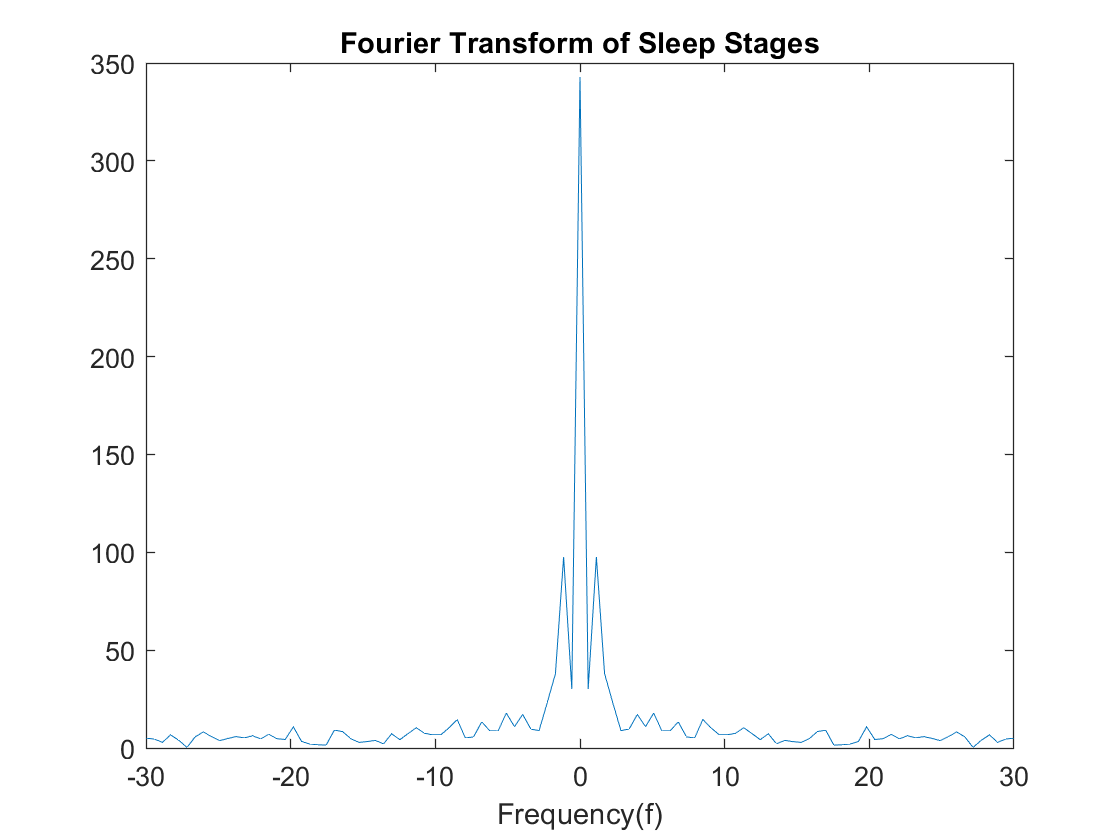

fs = 60;
% Frequency Vector
f = linspace(-fs/2,fs/2,numel(data2));
fft_sleep_stages_shift = fftshift(fft_sleep_stages);
plot(f,abs(fft_sleep_stages_shift));
title("Fourier Transform of Sleep Stages");
xlabel("Frequency(f)");

### **Question : How many times baby’s sleep cycle is completed during an hour?**

As you can see, the graph peaks 3 times(beside values near zero.). So baby’s sleep cycle is completed **3 times** during an hour.

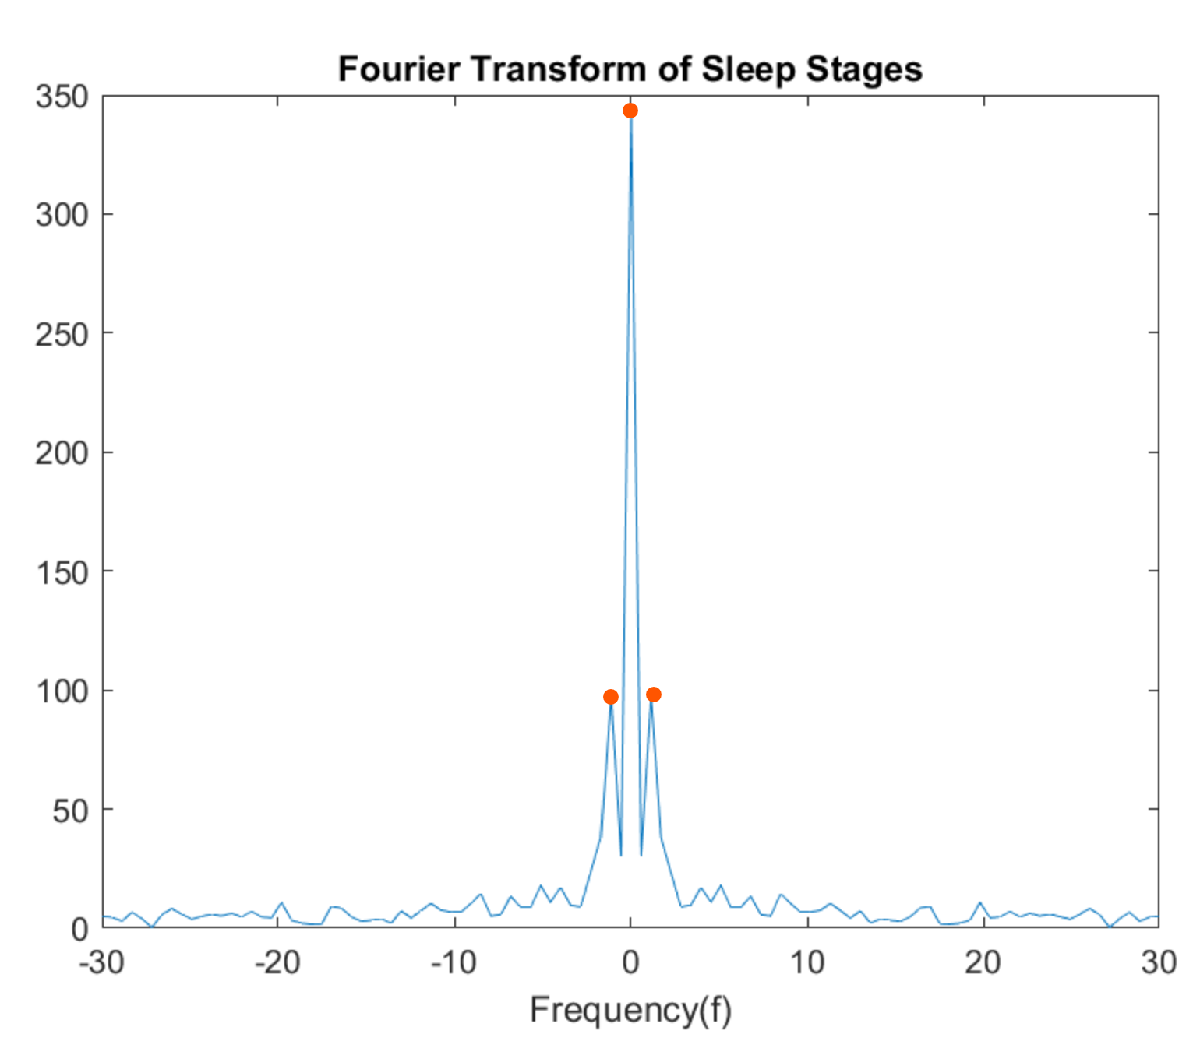

### **Question : **If we change order of indexes, is it still analysable?

## Assigning different indexes sleep stages

order of indexes : 1 1 2 2 3 3 -> qt qh tr al ah aw

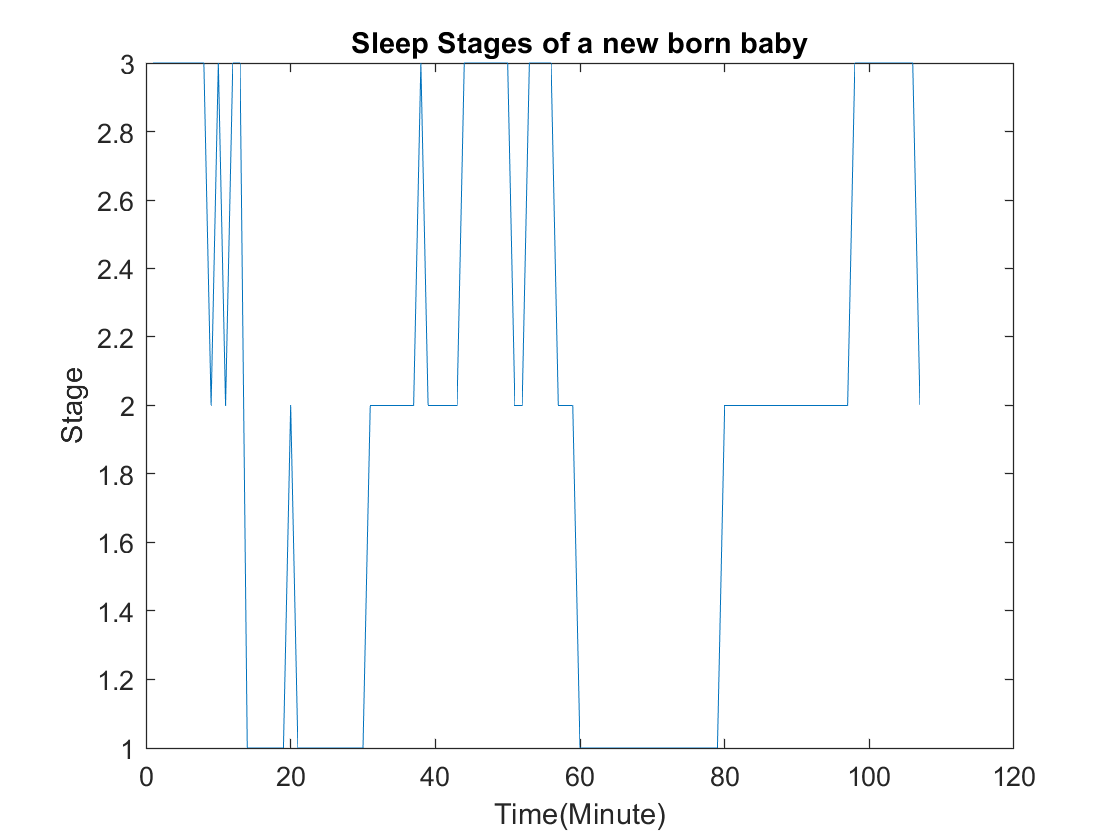

for i = 1:len
    if data(i) == "qt" || data(i) == "qh"
        data2(i) = 1;
    elseif data(i) == "tr" || data(i) == "al"
        data2(i) = 2;
    elseif data(i) == "ah" || data(i) == "aw"
        data2(i) = 3;
    end
end

plot(data2);
title("Sleep Stages of a new born baby");
ylabel("Stage");
xlabel("Time(Minute)");

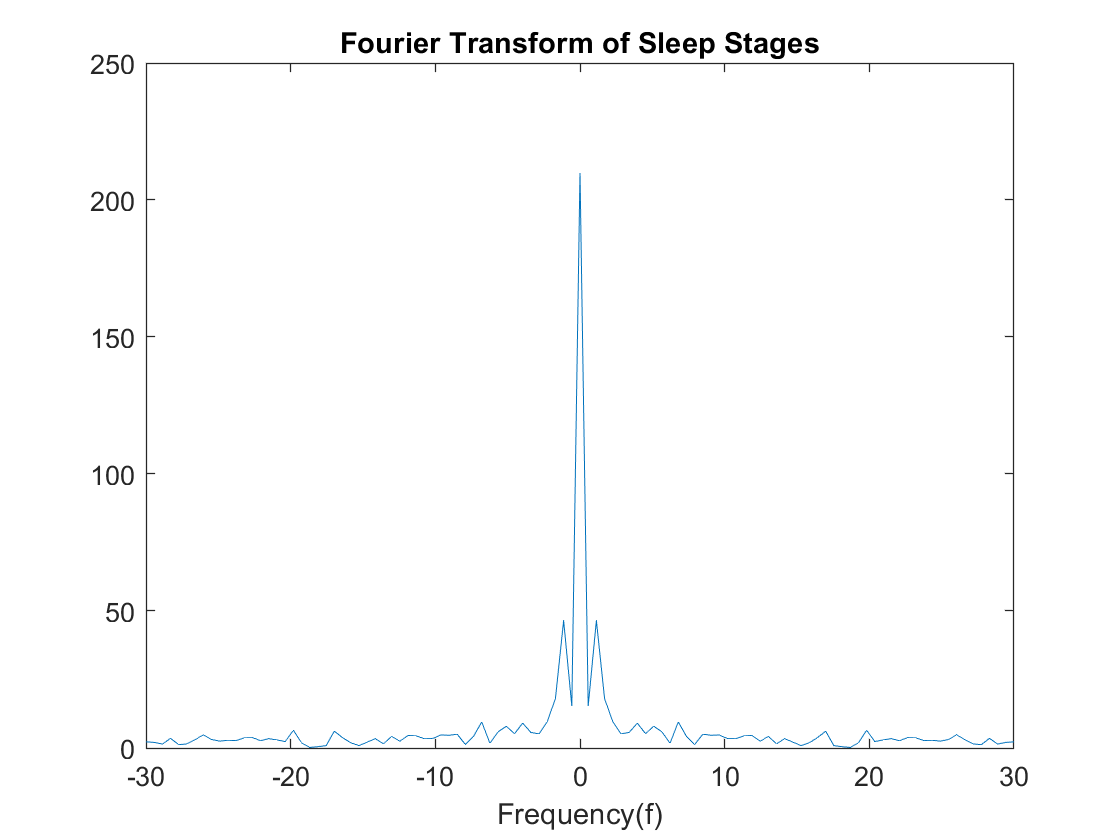

fft_sleep_stages = fft(data2);
% Frequency Vector
fft_sleep_stages_shift = fftshift(fft_sleep_stages);
plot(f,abs(fft_sleep_stages_shift));
title("Fourier Transform of Sleep Stages");
xlabel("Frequency(f)");

As you can see the results are **similar**.

### Question : Why changing the indexes didn't affect the results?